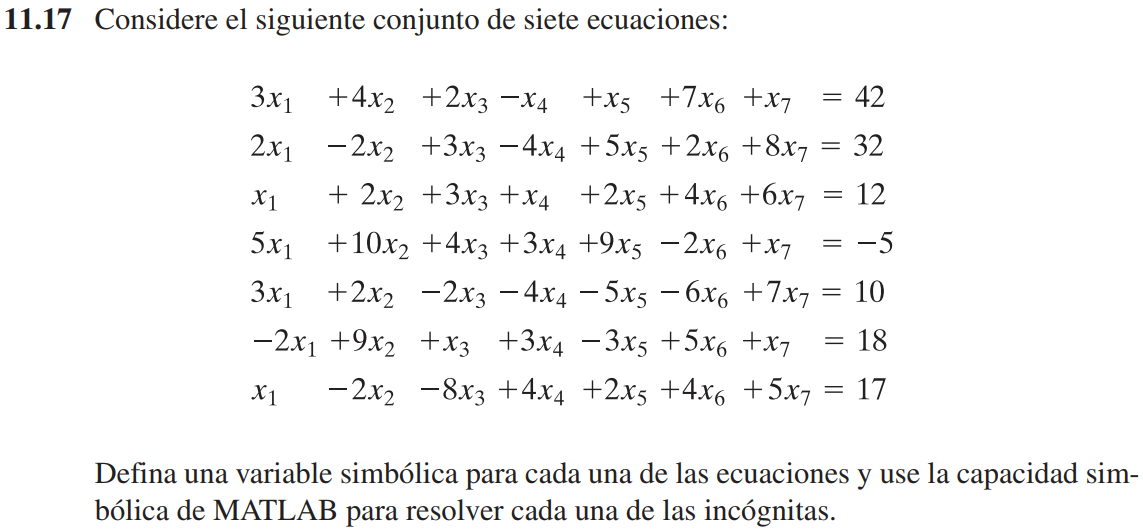

clear

syms x1 x2 x3 x4 x5 x6 x7
eq1 = 3*x1 + 4*x2 + 2*x3 - x4 + x5 + 7*x6 + x7 == 42;
eq2 = 2*x1 - 2*x2 + 3*x3 - 4*x4 + 5*x5 + 2*x6 + 8*x7 == 32;
eq3 = x1 + 2*x2 + 3*x3 + x4 + 2*x5 + 4*x6 + 6*x7 == 12;
eq4 = 5*x1 + 10*x2 + 4*x3 + 3*x4 + 9*x5 - 2*x6 + x7 == -5;
eq5 = 3*x1 + 2*x2 - 2*x3 - 4*x4 - 5*x5 - 6*x6 + 7*x7 == 10;
eq6 = -2*x1 + 9*x2 + x3 + 3*x4 - 3*x5 + 5*x6 + x7 == 18;
eq7 = x1 - 2*x2 - 8*x3 + 4*x4 + 2*x5 + 4*x6 + 5*x7 == 17;
eqsSym = [eq1; eq2; eq3; eq4; eq5; eq6; eq7]

S = solve(eqsSym)

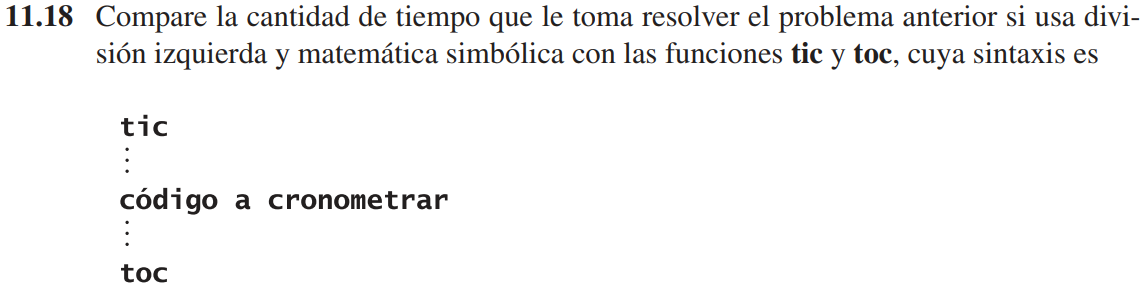

Se utilizará la variable `eqsSym` para no repetir código.

tic
    symSol = solve(eqsSym);     % Tiempo que toma determinar la solución de un sistema simb.
toc

A = [
    3 2 1 5 3 -2 1
    4 -2 2 10 2 9 -2
    2 3 3 4 -2 1 -8
    -1 -4 1 3 -4 3 4
    1 5 2 9 -5 -3 2
    7 2 4 -2 -6 5 4
    1 8 6 1 7 1 5
    ]';
B = [42 32 12 -5 10 18 17]';

tic
    matSol = A\B;       % Tiempo que toma determinar la solucion de un sistema matricial.
toc